# **변경사항**

### 2023.01.10

- macOS 설정 방법 설명 추가

- node 삭제 기능 추가

- edge color 설정 방법 변경

- edge가 검은색으로 나오는 오류 해결

- svg export 추가

- 2d network 예시 추가

### 2022.08.25

- spike 개수가 2 이상인 경우에만 sync score 계산하도록 수정

- network plot에서 node 크기를 키우고 채널 번호가 보이도록 수정

# **Python 설치 및 설정 방법**

**MacOS on Apple Silicon (e.g., M1, M2)**

- [https://www.anaconda.com/products/distribution#macos](https://www.anaconda.com/products/distribution#macos) 에서 Anaconda Distribution 다운로드하여 설치

- terminal 실행

- `conda create -n matalb_python python==3.9.2 입력하여 가상황경 생성 (matlab_python은 가상환경 이름이며 다른 이름으로 바꾸어도 됨, python==3.9.2 는 3.9.2 버전의 파이썬을 설치한다는 뜻이며 다른 버전으로 바꾸어도 됨)`

- `conda activate matlab_python 입력. (matlab_python)이라는 문구가 뜬다면 성공`

- `필요한 패키지 설치`

`    6. terminal에 ` `python`을 입력하여 python을 실행

         7. 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다

**Windows 10**

- [https://www.python.org/downloads/windows/](https://www.python.org/downloads/windows/) 에서 python 3.7, 3.8, 3.9 버전 중 하나를 windows installer로 다운로드받습니다.

- [https://wikidocs.net/8](https://wikidocs.net/8) 링크의 설명을 따라하여 설치를 완료합니다. Add Python 3.x to PATH 옵션을 꼭 체크합니다.

- windows powershell을 실행합니다. 윈도우 10이면 기본적으로 설치되어 있습니다.

-  powershell 창에 바로 아래 내용을 한 줄씩 입력하고 엔터를 칩니다.  각 명령어는 패키지 하나를 설치하는 명령어입니다. 실행되지 않으면 pip3 대신 pip를 입력합니다.

`pyspike 설치 시 io.h 파일이 없다는 오류 메시지가 나오면 `[`https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/`](https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/)` 에서 windows 10 sdk를 설치합니다.`

         5. 입력창에 `python`을 입력하여 python을 실행합니다. python 버전이 설치한 버전과 일치하는지 확인합니다.

          6. 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다(저는 macos에서 진행했기 때문에 윈도우와 파이썬 경로가 다릅니다).

# **작업 절차 - 2d network**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

## **1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/mac/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 소요시간 측정. 적지 않은 시간 소요됨

경과 시간은 77.732635초입니다.


## **2. networkAnalyzer 인스턴스 생성**

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9"); %  networkAnalyzer 클래스 인스턴스 생성

ans =   PythonEnvironment - 속성 있음:

          Version: "3.9"
       Executable: "/usr/local/opt/python@3.9/bin/python3.9"
          Library: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9"
           Status: Terminated
    ExecutionMode: OutOfProcess


## **3. 데이터 파일을 networkAnalyzer에 전달 **

na.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

Deleted previous data
Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
num

## **4. 사용하지 않는 채널 제거**

여기서는 17번-64번 채널을 모두 제거하겠습니다.

                %채널 번호
na.deleteChannel(17);

Deleted channal 17


idx_channelList = 17

63 channles left


na.deleteChannel(18);

Deleted channal 18


idx_channelList = 17

62 channles left


na.deleteChannel(19);

Deleted channal 19


idx_channelList = 17

61 channles left


na.deleteChannel(20);

Deleted channal 20


idx_channelList = 17

60 channles left


na.deleteChannel(21);

Deleted channal 21


idx_channelList = 17

59 channles left


na.deleteChannel(22);

Deleted channal 22


idx_channelList = 17

58 channles left


na.deleteChannel(23);

Deleted channal 23


idx_channelList = 17

57 channles left


na.deleteChannel(24);

Deleted channal 24


idx_channelList = 17

56 channles left


na.deleteChannel(25);

Deleted channal 25


idx_channelList = 17

55 channles left


na.deleteChannel(26);

Deleted channal 26


idx_channelList = 17

54 channles left


na.deleteChannel(27);

Deleted channal 27


idx_channelList = 17

53 channles left


na.deleteChannel(28);

Deleted channal 28


idx_channelList = 17

52 channles left


na.deleteChannel(29);

Deleted channal 29


idx_channelList = 17

51 channles left


na.deleteChannel(30);

Deleted channal 30


idx_channelList = 17

50 channles left


na.deleteChannel(31);

Deleted channal 31


idx_channelList = 17

49 channles left


na.deleteChannel(32);

Deleted channal 32


idx_channelList = 17

48 channles left


na.deleteChannel(33);

Deleted channal 33


idx_channelList = 17

47 channles left


na.deleteChannel(34);

Deleted channal 34


idx_channelList = 17

46 channles left


na.deleteChannel(35);

Deleted channal 35


idx_channelList = 17

45 channles left


na.deleteChannel(36);

Deleted channal 36


idx_channelList = 17

44 channles left


na.deleteChannel(37);

Deleted channal 37


idx_channelList = 17

43 channles left


na.deleteChannel(38);

Deleted channal 38


idx_channelList = 17

42 channles left


na.deleteChannel(39);

Deleted channal 39


idx_channelList = 17

41 channles left


na.deleteChannel(40);

Deleted channal 40


idx_channelList = 17

40 channles left


na.deleteChannel(41);

Deleted channal 41


idx_channelList = 17

39 channles left


na.deleteChannel(42);

Deleted channal 42


idx_channelList = 17

38 channles left


na.deleteChannel(43);

Deleted channal 43


idx_channelList = 17

37 channles left


na.deleteChannel(44);

Deleted channal 44


idx_channelList = 17

36 channles left


na.deleteChannel(45);

Deleted channal 45


idx_channelList = 17

35 channles left


na.deleteChannel(46);

Deleted channal 46


idx_channelList = 17

34 channles left


na.deleteChannel(47);

Deleted channal 47


idx_channelList = 17

33 channles left


na.deleteChannel(48);

Deleted channal 48


idx_channelList = 17

32 channles left


na.deleteChannel(49);

Deleted channal 49


idx_channelList = 17

31 channles left


na.deleteChannel(50);

Deleted channal 50


idx_channelList = 17

30 channles left


na.deleteChannel(51);

Deleted channal 51


idx_channelList = 17

29 channles left


na.deleteChannel(52);

Deleted channal 52


idx_channelList = 17

28 channles left


na.deleteChannel(53);

Deleted channal 53


idx_channelList = 17

27 channles left


na.deleteChannel(54);

Deleted channal 54


idx_channelList = 17

26 channles left


na.deleteChannel(55);

Deleted channal 55


idx_channelList = 17

25 channles left


na.deleteChannel(56);

Deleted channal 56


idx_channelList = 17

24 channles left


na.deleteChannel(57);

Deleted channal 57


idx_channelList = 17

23 channles left


na.deleteChannel(58);

Deleted channal 58


idx_channelList = 17

22 channles left


na.deleteChannel(59);

Deleted channal 59


idx_channelList = 17

21 channles left


na.deleteChannel(60);

Deleted channal 60


idx_channelList = 17

20 channles left


na.deleteChannel(61);

Deleted channal 61


idx_channelList = 17

19 channles left


na.deleteChannel(62);

Deleted channal 62


idx_channelList = 17

18 channles left


na.deleteChannel(63);

Deleted channal 63


idx_channelList = 17

17 channles left


na.deleteChannel(64);

Deleted channal 64


idx_channelList = 17

16 channles left


## **5. 노드 좌표 설정**

2d network이므로 높이를 모두 0으로 설정합니다.

%                 channlNum x  y  z
na.setChannelPosition3d(1 , 0, 0, 0)
na.setChannelPosition3d(2 , 0, 1, 0)
na.setChannelPosition3d(3 , 0, 2, 0)
na.setChannelPosition3d(4 , 0, 3, 0)
na.setChannelPosition3d(5 , 1, 0, 0)
na.setChannelPosition3d(6 , 1, 1, 0)
na.setChannelPosition3d(7 , 1, 2, 0)
na.setChannelPosition3d(8 , 1, 3, 0)

na.setChannelPosition3d(9 , 2, 0, 0)
na.setChannelPosition3d(10, 2, 1, 0)
na.setChannelPosition3d(11, 2, 2, 0)
na.setChannelPosition3d(12, 2, 3, 0)
na.setChannelPosition3d(13, 3, 0, 0)
na.setChannelPosition3d(14, 3, 1, 0)
na.setChannelPosition3d(15, 3, 2, 0)
na.setChannelPosition3d(16, 3, 3, 0)

## **6. spike detection**

na.bandPass([300,3000])
na.detectSpikes(4,2,2);

number of spikes found : 61
number of spikes found : 131
number of spikes found : 140
number of spikes found : 313
number of spikes found : 351
number of spikes found : 86
number of spikes found : 82
number of spikes found : 175
number of spikes found : 147
number of spikes found : 108
number of spikes found : 29
number of spikes found : 322
number of spikes found : 348
number of spikes found : 336
number of spikes found : 353
number of spikes found : 15


## **7. sync score 계산 및 확인**

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [16×1 containers.Map]
    channelList: [16×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [16×5 double]
     syncScores: []
      nConnects: []
          thres: 0.5000


filepath_score_matrix = "/Users/mac/GitHub/neurosignal-matlab/score_matrix.npy"

filepath_positions = "/Users/mac/GitHub/neurosignal-matlab/positions.pkl"

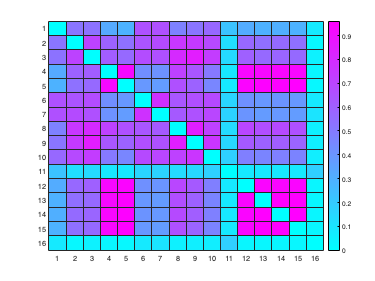

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [16×1 containers.Map]
    channelList: [16×1 double]
      nChannels: 16
        distMat: [16×16 double]
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [16×5 double]
     syncScores: [16×16 table]
      nConnects: []
          thres: 0.5000


thres = 0.5; %sync score 0.5 이상일 경우에만 연결된 것으로 간주 (network를 그릴 때에만 적용됨)
na.spikeDist(thres);

na.syncScores

ans = 16×16 table
               node1       node2       node3       node4       node5       node6       node7      node8       node9       node10      node11      node12      node13      node14      node15      node16 
              ________    ________    ________    ________    ________    ________    _______    ________    ________    ________    ________    ________    ________    ________    ________    ________

    node1            0     0.52083     0.52736     0.32086     0.29126     0.65306    0.65734     0.47458     0.51923     0.56805     0.22222     0.31332      0.2934     0.30227     0.28986    0.078947
    node2      0.52083           0     0.70849     0.58559     0.53527     0.64516    0.67606     0.75163     0.74101     0.68619       0.125     0.56954      0.5428     0.55675     0.53719    0.027397
    node3      0.52736     0.70849           0     0.60927     0.56619     0.67257    0.65766         0.8     0.85017     0.73387     0.14201      0.5974     0.56557     0.5

na.nConnects

ans = 16×1 table
              number of connected
              ___________________

    node1              6         
    node2             13         
    node3             13         
    node4             10         
    node5              9         
    node6              7         
    node7              7         
    node8             12         
    node9             13         
    node10             8         
    node11             0         
    node12             9         
    node13             9         
    node14             9         
    node15             9         
    node16             0         


## **8. 네트워크 그리기**

설정한 degree 범위 내의 node만 그리기

degree_lim = [0, 20]; % look at na.nConnects and determine the degree range

설정한 sync score 범위 내의 edge만 그리기

edge_lim = [0.6, 1] % the min value must be larger than the threshold value

edge_lim =     0.6000    1.0000


colorbar 범위 지정

edge_colorbar_lim = [0.6, 1] % 

edge_colorbar_lim =     0.6000    1.0000


community_colorbar_max = 20

community_colorbar_max = 20

표시 옵션 지정

display_community_color= false

display_community_color = logical
   0


display_degree = true

display_degree = logical
   1


display_sync_score = true

display_sync_score = logical
   1


그림 그리기: 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

edge colormap 색깔 코드를 hex code로 입력합니다. [https://www.color-hex.com/](https://www.color-hex.com/) 여기서 검색해서 찾으시면 됩니다.

저는 하늘색에서 시작해 남색에서 끝나는 것으로 했습니다.



%        basic_size,  multiplier     edge_startcolor,    edge_endcolor   colorscale_node        degree_lim,       edge_lim
na.louvain(10,         20,            '#9fcbee',          "#01016f"       ,'oranges',         degree_lim,        edge_lim,    edge_colorbar_lim,   community_colorbar_max, display_community_color, display_degree, display_sync_score)

ans = 0

## 2. networkAnalyzer 클래스 인스턴스 생성

**class **`networkAnalyzer`

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9");

ans =   PythonEnvironment - 속성 있음:

          Version: "3.9"
       Executable: "/usr/local/opt/python@3.9/bin/python3.9"
          Library: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9/lib/libpython3.9.dylib"
             Home: "/usr/local/opt/python@3.9/Frameworks/Python.framework/Versions/3.9"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


na.addChannels(reader); % 채널 object를 networkAnalyzer에 입력


## 3. 채널 object를 networkAnalyzer에 입력

na.addChannels(reader);

Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×4 double]
     syncScores: []
      nConnects: []


na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: []
        distMat: []
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×4 double]
     syncScores: []
      nConnects: []


## 4. 채널 위치 입력

method `setChannelPosition2d`

input argument:

- channel number

- 해당 channel의 x좌표

- 해당 channel의 y좌표

- 해당 channel의 z좌표

좌표는 좌표평면의 1사분면을 생각하면 됩니다. (0,0)의 한 칸 위가 (0,1)이고 한 칸 오른쪽이 (1,0)입니다. 아래 코드로 설정한 위치를 그림으로 그리면 아래 그림처럼 됩니다.

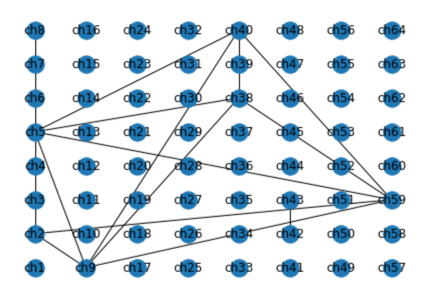

%                 channlNum x  y  z
na.setChannelPosition3d(1 , 0, 0, 0)
na.setChannelPosition3d(2 , 0, 1, 0)
na.setChannelPosition3d(3 , 0, 2, 0)
na.setChannelPosition3d(4 , 0, 3, 0)
na.setChannelPosition3d(5 , 1, 0, 0)
na.setChannelPosition3d(6 , 1, 1, 0)
na.setChannelPosition3d(7 , 1, 2, 0)
na.setChannelPosition3d(8 , 1, 3, 0)
na.setChannelPosition3d(9 , 2, 0, 0)
na.setChannelPosition3d(10, 2, 1, 0)
na.setChannelPosition3d(11, 2, 2, 0)
na.setChannelPosition3d(12, 2, 3, 0)
na.setChannelPosition3d(13, 3, 0, 0)
na.setChannelPosition3d(14, 3, 1, 0)
na.setChannelPosition3d(15, 3, 2, 0)
na.setChannelPosition3d(16, 3, 3, 0)

na.setChannelPosition3d(17,  0, 0, 1.5)
na.setChannelPosition3d(18,  0, 1, 1.5)
na.setChannelPosition3d(19,  0, 2, 1.5)
na.setChannelPosition3d(20,  0, 3, 1.5)
na.setChannelPosition3d(21,  1, 0, 1.5)
na.setChannelPosition3d(22,  1, 1, 1.5)
na.setChannelPosition3d(23,  1, 2, 1.5)
na.setChannelPosition3d(24,  1, 3, 1.5)
na.setChannelPosition3d(25,  2, 0, 1.5)
na.setChannelPosition3d(26,  2, 1, 1.5)
na.setChannelPosition3d(27,  2, 2, 1.5)
na.setChannelPosition3d(28,  2, 3, 1.5)
na.setChannelPosition3d(29,  3, 0, 1.5)
na.setChannelPosition3d(30,  3, 1, 1.5)
na.setChannelPosition3d(31,  3, 2, 1.5)
na.setChannelPosition3d(32,  3, 3, 1.5)

na.setChannelPosition3d(33,  0, 0, 3)
na.setChannelPosition3d(34,  0, 1, 3)
na.setChannelPosition3d(35,  0, 2, 3)
na.setChannelPosition3d(36,  0, 3, 3)
na.setChannelPosition3d(37,  1, 0, 3)
na.setChannelPosition3d(38,  1, 1, 3)
na.setChannelPosition3d(39,  1, 2, 3)
na.setChannelPosition3d(40,  1, 3, 3)
na.setChannelPosition3d(41,  2, 0, 3)
na.setChannelPosition3d(42,  2, 1, 3)
na.setChannelPosition3d(43,  2, 2, 3)
na.setChannelPosition3d(44,  2, 3, 3)
na.setChannelPosition3d(45,  3, 0, 3)
na.setChannelPosition3d(46,  3, 1, 3)
na.setChannelPosition3d(47,  3, 2, 3)
na.setChannelPosition3d(48,  3, 3, 3)

na.setChannelPosition3d(49, 0, 0, 4.5)
na.setChannelPosition3d(50, 0, 1, 4.5)
na.setChannelPosition3d(51, 0, 2, 4.5)
na.setChannelPosition3d(52, 0, 3, 4.5)
na.setChannelPosition3d(53, 1, 0, 4.5)
na.setChannelPosition3d(54, 1, 1, 4.5)
na.setChannelPosition3d(55, 1, 2, 4.5)
na.setChannelPosition3d(56, 1, 3, 4.5)
na.setChannelPosition3d(57, 2, 0, 4.5)
na.setChannelPosition3d(58, 2, 1, 4.5)
na.setChannelPosition3d(59, 2, 2, 4.5)
na.setChannelPosition3d(60, 2, 3, 4.5)
na.setChannelPosition3d(61, 3, 0, 4.5)
na.setChannelPosition3d(62, 3, 1, 4.5)
na.setChannelPosition3d(63, 3, 2, 4.5)
na.setChannelPosition3d(64, 3, 3, 4.5)


na.positions

ans =      1     1     0     0     0
     2     2     0     1     0
     3     3     0     2     0
     4     4     0     3     0
     5     5     1     0     0
     6     6     1     1     0
     7     7     1     2     0
     8     8     1     3     0
     9     9     2     0     0
    10    10     2     1     0


## 5. 모든 채널에 bandpass 적용하고 spike detection 수행

summary_examples_firing_rate.mlx 파일의 [0.4. bandpass filter 적용] [0.5. (method) `detectSpikes] 섹션 참조`

na.bandPass([300,3000])
na.detectSpikes(4,2,2);

number of spikes found : 61
number of spikes found : 131
number of spikes found : 140
number of spikes found : 313
number of spikes found : 351
number of spikes found : 86
number of spikes found : 82
number of spikes found : 175
number of spikes found : 147
number of spikes found : 108
number of spikes found : 29
number of spikes found : 322
number of spikes found : 348
number of spikes found : 336
number of spikes found : 353
number of spikes found : 15
number of spikes found : 177
number of spikes found : 87
number of spikes found : 319
number of spikes found : 351
number of spikes found : 348
number of spikes found : 53
number of spikes found : 77
number of spikes found : 40
number of spikes found : 75
number of spikes found : 100
number of spikes found : 152
number of spikes found : 322
number of spikes found : 278
number of spikes found : 186
number of spikes found : 160
number of spikes found : 17
number of spikes found : 163
number of spikes found : 276
number of spikes found : 

## 6. sync score matrix heatmap

figure 3 a, b, c, d, e의 (i)

pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도(혹은 거리)를 측정합니다.

spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 함수가 작동하지 않습니다. 따라서 이 때에는 거리 계산값이 NaN이 되도록 함수를 수정하였습니다(2022.08.24)

NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

아래 사항은 아직 구현하지 않았습니다(reference 12페이지에 있는 내용) 

Since two spike trains with uniformly random activity may exhibit relatively high synchrony merely due to randomness, the SPIKE-distance from recorded data was normalized to random samples generated computationally. That is, for a pair of electrodes with $n_1$ and $n_2$ spikes,

- random spike trains were generated by **sampling $n_1$ and $n_2$ points uniformly at random in a 10-minute timeline.**

- This process was **repeated 1,000 times**, and the **average normalized score** is reported.

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: 64
        distMat: [64×64 double]
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×5 double]
     syncScores: [64×64 table]
      nConnects: [64×1 table]
          thres: 0.8000


filepath_score_matrix = "/Users/mac/GitHub/neurosignal-matlab/score_matrix.npy"

filepath_positions = "/Users/mac/GitHub/neurosignal-matlab/positions.pkl"

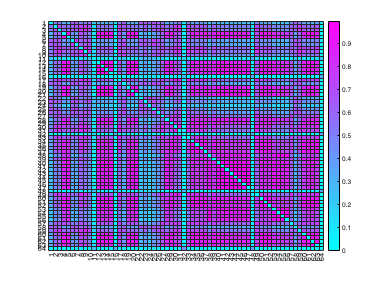

na =   networkAnalyzer - 속성 있음:

    spikeTrains: []
       channels: [64×1 containers.Map]
    channelList: [64×1 double]
      nChannels: 64
        distMat: [64×64 double]
       filepath: "/Users/mac/GitHub/neurosignal-matlab"
     pythonpath: "/usr/local/opt/python@3.9/bin/python3.9"
    ChannelList: []
      positions: [64×5 double]
     syncScores: [64×64 table]
      nConnects: [64×1 table]
          thres: 0.8000


ans =          0    0.5208    0.5274    0.3209    0.2913    0.6531    0.6573    0.4746    0.5192    0.5680    0.2222    0.3133    0.2934    0.3023    0.2899    0.0789    0.4874    0.6351    0.3158    0.2913    0.2934    0.6491    0.6812    0.5941    0.6765    0.6460    0.5070    0.3185    0.3540    0.4696    0.5249    0.0769    0.4911    0.3561    0.3762    0.3859    0.3614    0.2285    0.3582    0.2679    0.2661    0.2675    0.2641    0.2641    0.2614    0.2603    0.2603    0.1299    0.4777    0.3324
    0.5208         0    0.7085    0.5856    0.5353    0.6452    0.6761    0.7516    0.7410    0.6862    0.1250    0.5695    0.5428    0.5567    0.5372    0.0274    0.7532    0.6514    0.5689    0.5394    0.5344    0.5326    0.6442    0.4327    0.6311    0.5974    0.6784    0.5430    0.6259    0.7508    0.7491    0.0541    0.7279    0.6290    0.6581    0.6667    0.6219    0.4272    0.6272    0.5058    0.5029    0.4943    0.4774    0.4737    0.4764    0.4783    0.4783    0.0952    0.7508   

thres = 0.8

na.spikeDist(thres)




###  network mapping 을 위해 계산하는 parameter 확인

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na.syncScores

ans = 64×64 table
               node1       node2       node3       node4       node5       node6       node7      node8       node9       node10      node11      node12      node13      node14      node15      node16      node17      node18      node19      node20      node21     node22      node23      node24      node25      node26     node27      node28      node29      node30      node31      node32     node33      node34      node35      node36      node37      node38      node39      node40      node41      node42      node43      node44      node45      node46      node47      node48      node49      node50      node51      node52      node53      node54      node55      node56     node57      node58     node59      node60      node61      node62      node63      node64 
              ________    ________    ________    ________    ________    ________    _______    ________    ________    ________    ________    ________    ________    ________    ________    ________    ____

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na.nConnects

ans = 64×1 table
              number of connected
              ___________________

    node1              0         
    node2              0         
    node3              6         
    node4             31         
    node5             35         
    node6              0         
    node7              0         
    node8              8         
    node9              5         
    node10             0         
    node11             0         
    node12            33         
    node13            35         
    node14            35         
    node15            35         
    node16             0         


## 7. network plot(3d)

method `louvain()`

figure 3 a, b, c, d, e의 (ii)

matlab에서 python을 통해 networkx로 네트워크를 만들고 louvain-python으로 community detection을 하는 것까지는 별 문제가 없으나,

네트워크 모양을 plot으로 그리는 것은 matplotlib 라이브러리를 써야 하는데, 이상하게도 matlab에서 연동이 잘 안됩니다.

차선책으로, score matrix를 파일로 저장한 다음 아예 파이썬 스크립트를 만들고 matlab에서는 해당 파이썬 스크립트를 실행하는 명령만 내리도록 조치하였습니다.

plot은 이 파일이 있는 경로에 `networkfig.html`로 저장됩니다.

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

- 노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. (`basic_size + multiplier * ( 1 - 2) )`

- edge, node의 colorscale은 다양한 포맷( hexa code, rgb code, or names css colors)으로 지정 가능합니다 (see "Built-In Sequential Color scales" in  https://plotly.com/python/builtin-colorscales/ )

node colors are entered as varaious formats, including hexa code, rgb code, or names css colors: 

see "Built-In Sequential Color scales" in  [https://plotly.com/python/builtin-colorscales/](https://plotly.com/python/builtin-colorscales/) 

degree_lim = [0, 40] % look at na.nConnects and determine the degree range

degree_lim =      0    40


edge_lim = [0.9, 1] % the min value must be larger than the threshold value

edge_lim =     0.9000    1.0000


아래 값은 sync score colorbar 범위를 통일시키는 기능을 합니다. edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.

edge_colorbar_lim = [0.4, 1] % 

community_colorbar_max 값은 일단 큰 값(<=전극 수)로 두시고, community_info.csv에서 클러스터 수를 확인하신 후 그 값으로 바꾸시면 됩니다.

이 변수는 모든 plot에서 community colorbar를 통일하는 기능을 합니다. 예를 들어, 이 값을 20으로 설정하면 colorbar에서 community 번호의 범위가 1-20이 되고, 20번 커뮤니티에 가장 진한 색이 배정됩니다.

community_colorbar_max = 20

edge_colorbar_lim =     0.4000    1.0000


display_community_color= false
display_degree = true
display_sync_score = true

community_colorbar_max = 20

아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

display_community_color = logical
   0


%        basic_size,  multiplier     colorscale_edge,       colorscale_node        degree_lim,       edge_lim

display_degree = logical
   0


na.louvain(10,         20,            'teal'                    ,'oranges',         degree_lim,        edge_lim,    edge_colorbar_lim,   community_colorbar_max, display_community_color, display_degree, display_sync_score)

display_sync_score = logical
   0


ans = 0